# Acoustic Triangulation System Simulation using TDoA Technique

## Authors: Bonga Njamela, Charles Portman, Morris Nkomo

#### Date: 13 Sept 2023

## Introduction

We simulate TDoA measurements from a single sound source and use them to localize and track the source in the absence of noise and any other signals that can lead to missed detections. Adapted from the Mathworks "Object Tracking Using Time Difference of Arrival (TDOA)" simulation.

## Define 2-D Scenario

We define a 2-D scenario using the compute function which returns a trackingScenarioRecording object representing a single sound source moving at a constant velocity. The sound source is observed by 4 stationary, spatially-separated microphones. The compute function also returns a matrix of two columns representing the pairs formed by the receivers. Each row represents the PlatformID of the platforms that form the TDoA measurement.

import 


ans =

  0×1 empty cell array



% Reproducible results
rng(2021);

% Setup scenario with 4 receivers
numReceivers = 4;
[scenario, rxPairs] = computeCreateSingleTargetTDOAScenario(numReceivers);

## Simulate TDoA Measurements from Sound Source

Use computeSimulateTDOA function to simulate TDoA measurements from the objects. The compute function allows you to specify the measurement accuracy in the TDoA. The timing inaccuracy in the clocks as well as TDoA estimations is assumed to be 100 ns. The emission speed and units of the reported time can be specified using the computeGetGlobalParameters funciton. The computeSimulateTDoA function returns the TDoA detections as a cell arrayof objectDetection objects.


%computeGetGlobalParameters(); %set speed of sound c
measNoise = 1000; %measurement noise variance nanosecond^2
tdoaDets = computeSimulateTDOA(scenario, rxPairs, measNoise);

% Each TDoA detection is represented using the objectDetection according to the following format:



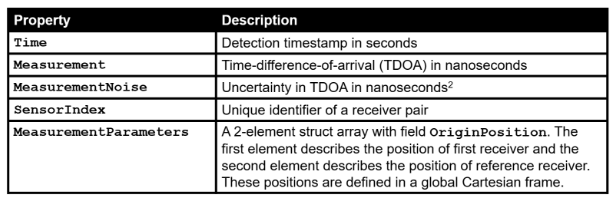

## Generate TDoA Detections From Sound Source

Uses the computeTDOA2Pos function to estimate the position and position covariance of the acoustic source at every step using the spherical intersection algorithm. Further filter the position estimate of the object using a global nearest neighbor (GNN) tracker configured using the trackerGNN System object™ with a constant-velocity linear Kalman filter as adapated from the MathWorks object tracking example. To account for the high speed of the object, this constant velocity Kalman filter is configured using the compute function, computeInitHighSpeedKF.

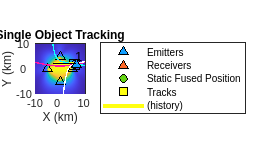


% Define accuracy in measurements
measNoise = (100)^2; % nanoseconds^2

% Display object
display = ComputeTDOATrackingExampleDisplay(XLimits=[-1e4 1e4],...
                                           YLimits=[-1e4 1e4],...
                                           LogAccuracy=true,...
                                           Title="Single Object Tracking");

% Create a GNN tracker
tracker = trackerGNN(FilterInitializationFcn=@computeInitHighSpeedKF,...
                     AssignmentThreshold=100);

while advance(scenario)
    % Elapsed time
    time = scenario.SimulationTime;

    % Simulate TDOA detections without false alarms and missed detections
    tdoaDets = computeSimulateTDOA(scenario, rxPairs, measNoise);

    % Get estimated position and position covariance as objectDetection
    % objects
    posDet = computeTDOA2Pos(tdoaDets,true);

    % Update the tracker with position detections
    tracks = tracker(posDet, time);

    % Display results
    display(scenario, rxPairs, tdoaDets, {posDet}, tracks);
end

## Supporting Functions

Contains all the compute functions used to compute TDoA.

`computeTDOA2Pos`

This function uses the spherical intersection algorithm to find the object position from the TDOA detections assumed to be from the same object. This function assumes that all TDOAs are measured with respect to the same reference sensor. 

- **[pos, posCov] = computeTDOA2Pos(tdoaDets):** returns the estimated position and position uncertainty covariance.

- **posDetection = computeTDOA2Pos(tdoaDets, true):** returns the estimate position and uncertainty covariance as an objectDetection object. 

function varargout = computeTDOA2Pos(tdoaDets, reportDetection)

if nargin < 2
    reportDetection = false;
end

% Collect scaling information
params = computeGetGlobalParameters;
emissionSpeed = params.EmissionSpeed;
timeScale = params.TimeScale;

% Location of the reference receiver
referenceLoc = tdoaDets{1}.MeasurementParameters(2).OriginPosition(:);

% Formulate the problem. See [1] for more details
d = zeros(numel(tdoaDets),1);
delta = zeros(numel(tdoaDets),1);
S = zeros(numel(tdoaDets),3);
for i = 1:numel(tdoaDets)
    receiverLoc = tdoaDets{i}.MeasurementParameters(1).OriginPosition(:);
    d(i) = tdoaDets{i}.Measurement*emissionSpeed/timeScale;
    delta(i) = norm(receiverLoc - referenceLoc)^2 - d(i)^2;
    S(i,:) = receiverLoc - referenceLoc;
end

% Pseudo-inverse of S
Swstar = pinv(S);

% Assemble the quadratic range equation
STS = (Swstar'*Swstar);
a = 4 - 4*d'*STS*d;
b = 4*d'*STS*delta;
c = -delta'*STS*delta;

Rs = zeros(2,1);
% Imaginary solution, return a location outside coverage
if b^2 < 4*a*c 
    varargout{1} = 1e10*ones(3,1);
    varargout{2} = 1e10*eye(3);
    return;
end

% Two range values
Rs(1) = (-b + sqrt(b^2 - 4*a*c))/(2*a);
Rs(2) = (-b - sqrt(b^2 - 4*a*c))/(2*a);

% If one is negative, use the positive solution
if prod(Rs) < 0
    Rs = Rs(Rs > 0);
    pos = 1/2*Swstar*(delta - 2*Rs(1)*d) + referenceLoc;
else % Use range which minimize the error
    xs1 = 1/2*Swstar*(delta - 2*Rs(1)*d);
    xs2 = 1/2*Swstar*(delta - 2*Rs(2)*d);
    e1 = norm(delta - 2*Rs(1)*d - 2*S*xs1);
    e2 = norm(delta - 2*Rs(2)*d - 2*S*xs2);
    if e1  > e2
        pos = xs2 + referenceLoc;
    else
        pos = xs1 + referenceLoc;
    end
end

% If required, compute the uncertainty in the position
if nargout > 1 || reportDetection
    posCov = computeCalcPositionCovariance(pos,tdoaDets,timeScale,emissionSpeed);
end

if reportDetection
    varargout{1} = objectDetection(tdoaDets{1}.Time,pos,'MeasurementNoise',posCov);
else
    varargout{1} = pos;
    if nargout > 1
        varargout{2} = posCov;
    end
end

end

function measCov = computeCalcPositionCovariance(pos,thisDetections,timeScale,emissionSpeed)
n = numel(thisDetections);
% Complete Jacobian from position to N TDOAs
H = zeros(n,3);
% Covariance of all TDOAs
S = zeros(n,n);
for i = 1:n
   e1 = pos - thisDetections{i}.MeasurementParameters(1).OriginPosition(:);
   e2 = pos - thisDetections{i}.MeasurementParameters(2).OriginPosition(:);
   Htdoar1 = (e1'/norm(e1))*timeScale/emissionSpeed;
   Htdoar2 = (e2'/norm(e2))*timeScale/emissionSpeed;
   H(i,:) = Htdoar1 - Htdoar2;
   S(i,i) = thisDetections{i}.MeasurementNoise;
end
Pinv = H'/S*H;
% Z is not measured, use 1 as the covariance
if Pinv(3,3) < eps
    Pinv(3,3) = 1;
end

% Insufficient information in TDOA
if rank(Pinv) >= 3
    measCov = eye(3)/Pinv;
else
    measCov = inf(3);
end

% Replace inf with large number
measCov(~isfinite(measCov)) = 100;

% Return a true symmetric, positive definite matrix for covariance.
measCov = (measCov + measCov')/2;
end


`computeInitHighSpeedKF`

This function initializes a constant velocity Kalman filter and sets a higher initial state covariance on velocity components to account for high speed of the object vehicles.

function filter = computeInitHighSpeedKF(detection)
filter = initcvkf(detection);
filter.StateCovariance(2:2:end,2:2:end) = 500*eye(3);
end

`computeTOA2Pos`

This function computes the position and emission time of a target given its time-of-arrival detections from multiple receivers.

 
function [posTime, posTimeCov] = computeTOA2Pos(toaDetections)
% This function computes the position and emission time of a target given
% its time-of-arrival detections from multiple receivers. 

% Convert TOAs to TDOAs for using spherical intersection
[tdoaDetections, isValid] = computeTOA2TDOADetections(toaDetections);

% At least 3 TOAs (2 TDOAs) required. Some TOA pairings can lead to an
% invalid TDOA (> maximum TDOA). In those situations, discard the tuple by
% using an arbitrary position with a large covariance.
if numel(tdoaDetections) < 2 || any(~isValid)
    posTime = 1e10*ones(4,1);
    posTimeCov = 1e10*eye(4);
else
    % Get position estimate using TDOA fusion. 
    % Get time estimate using calculated position.
    if nargout > 1 % Only calculate covariance when requested to save time
        [pos, posCov] = computeTDOA2Pos(tdoaDetections);
        [time, timeCov] = computeCalcEmissionTime(toaDetections, pos, posCov);
        posTime = [pos;time];
        posTimeCov = blkdiag(posCov,timeCov);
    else
        pos = computeTDOA2Pos(tdoaDetections);
        time = computeCalcEmissionTime(toaDetections, pos);
        posTime = [pos;time];
    end
end
end


**computeCalcEmissionTime**

This function calculates the emission time of an object given its position and obtained TOA detections. It also computes the uncertainty in the estimate time. 


function [time, timeCov] = computeCalcEmissionTime(toaDetections, pos, posCov)
globalParams = computeGetGlobalParameters;
emissionSpeed = globalParams.EmissionSpeed;
timeScale = globalParams.TimeScale;
n = numel(toaDetections);
emissionTime = zeros(n,1);
emissionTimeCov = zeros(n,1);
for i = 1:numel(toaDetections)
    % Calculate range from this receiver
    p0 = toaDetections{i}.MeasurementParameters.OriginPosition(:);
    r = norm(pos - p0);
    emissionTime(i) = toaDetections{i}.Measurement - r/emissionSpeed*timeScale;
    if nargout > 1
        rJac = (pos - p0)'/r;
        rCov = rJac*posCov*rJac';
        emissionTimeCov(i) = rCov./emissionSpeed^2*timeScale^2;
    end
end
% Gaussian merge each time and covariance estimate
time = mean(emissionTime);
if nargout > 1
    e = emissionTime - time;
    timeCov = mean(emissionTimeCov) + mean(e.^2);
end
end


`computeMeasureTOA`

This function calculates the expected TOA at a receiver given an object position and emission time and the receiver's measurement parameters (OriginPosition).

function toa = computeMeasureTOA(posTime, params)
globalParams = computeGetGlobalParameters;
emissionSpeed = globalParams.EmissionSpeed;
timeScale = globalParams.TimeScale;
r = norm(posTime(1:3) - params.OriginPosition);
toa = posTime(4) + r/emissionSpeed*timeScale;
end

`computeMeasureTDOA`

function toa = computeMeasureTDOA(pos, params)
% This function calculates the expected TDOA measurement given object
% position and measurement parameters of a TDOA detection
globalParams = computeGetGlobalParameters;
emissionSpeed = globalParams.EmissionSpeed;
timeScale = globalParams.TimeScale;
r1 = norm(pos(1:3) - params(1).OriginPosition);
r2 = norm(pos(1:3) - params(2).OriginPosition);
toa = (r1 - r2)/emissionSpeed*timeScale;
end